# Chapter 7 Boundary Value Problems Examples

#### Example 7.2

% Define ODE function
f = @(t, y) [y(2), y(1) + y(2)];

% Define BVP parameters
tspan = [0, 1];     % boundaries of the t domain
bvals = [0, 2];     % boundary values
h = 0.2;            % step length
s = [1, 2, 1.5];    % guess values

% Calculate the solution to the IVP for the different guess values
[t, y1] = solveIVP(f, tspan, [bvals(1), s(1)], h, @euler);
[t, y2] = solveIVP(f, tspan, [bvals(1), s(2)], h, @euler);
[t, y3] = solveIVP(f, tspan, [bvals(1), s(3)], h, @euler);

% Print table of solutions
for i = 1 : 1
    fprintf("s = %0.2f", y1(1,2))
    fprintf("|  $t$  |  $y_1$   |  $y_2$   |")
    fprintf("|:-----:|:--------:|:--------:|")
    for n = 1 : length(t)
        fprintf("| %5.2f | %7.6f | %7.6f |\n", t(n), y1(n,1), y1(n,2))
    end
end

s = 1.00

|  $t$  |  $y_1$   |  $y_2$   |

|:-----:|:--------:|:--------:|

|  0.00 | 0.000000 | 1.000000 |
|  0.20 | 0.200000 | 1.200000 |
|  0.40 | 0.440000 | 1.480000 |
|  0.60 | 0.736000 | 1.864000 |
|  0.80 | 1.108800 | 2.384000 |
|  1.00 | 1.585600 | 3.082560 |


for i = 1 : 1
    fprintf("s = %0.2f", y1(1,2))
    fprintf("|  $t$  |  $y_1$   |  $y_2$   |")
    fprintf("|:-----:|:--------:|:--------:|")
    for n = 1 : length(t)
        fprintf("| %5.2f | %7.6f | %7.6f |\n", t(n), y2(n,1), y2(n,2))
    end
end

s = 1.00

|  $t$  |  $y_1$   |  $y_2$   |

|:-----:|:--------:|:--------:|

|  0.00 | 0.000000 | 2.000000 |
|  0.20 | 0.400000 | 2.400000 |
|  0.40 | 0.880000 | 2.960000 |
|  0.60 | 1.472000 | 3.728000 |
|  0.80 | 2.217600 | 4.768000 |
|  1.00 | 3.171200 | 6.165120 |


for i = 1 : 1
    fprintf("s = %0.2f", y1(1,2))
    fprintf("|  $t$  |  $y_1$   |  $y_2$   |")
    fprintf("|:-----:|:--------:|:--------:|")
    for n = 1 : length(t)
        fprintf("| %5.2f | %7.6f | %7.6f |\n", t(n), y3(n,1), y3(n,2))
    end
end

s = 1.00

|  $t$  |  $y_1$   |  $y_2$   |

|:-----:|:--------:|:--------:|

|  0.00 | 0.000000 | 1.500000 |
|  0.20 | 0.300000 | 1.800000 |
|  0.40 | 0.660000 | 2.220000 |
|  0.60 | 1.104000 | 2.796000 |
|  0.80 | 1.663200 | 3.576000 |
|  1.00 | 2.378400 | 4.623840 |


#### Example 7.3

% Define ODE function
f = @(t, y) [y(2), y(1) + y(2)];

% Define BVP parameters
tspan = [0, 1];     % boundaries of the t domain
bvals = [0, 2];     % boundary values
h = 0.2;            % step length

% Solve BVP using the shooting method
[t, y] = shooting_method(f, tspan, bvals, h, @euler, 1e-4);

sold = 1

sold = 0.2923

sold = 1.2614


% Plot solution
y

y =          0    1.2614
    0.2523    1.5136
    0.5550    1.8668
    0.9284    2.3512
    1.3986    3.0071
    2.0000    3.8882


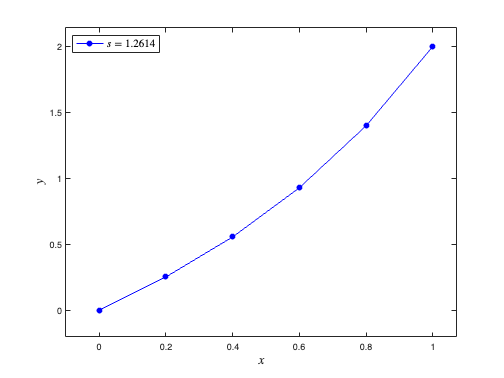

plot(t, y(:,1), "b-o", MarkerFaceColor="b")
xlabel("$x$", FontSize=14, Interpreter="latex")
ylabel("$y$", FontSize=14, Interpreter="latex")
legend(sprintf("$s = %0.4f$", y(1,2)), Fontsize=12, Interpreter="latex", Location="northwest")
axis padded

## Functions

#### Single step solver

function [t, y] = solveIVP(f, tspan, y0, h, solver, tol)

% Define t and y arrays
nsteps = floor((tspan(2) - tspan(1)) / h);
t = tspan(1) : h : tspan(2);
y = zeros(nsteps + 1, length(y0));
y(1,:) = y0;

% Loop through the steps and calculate single step solver solution
for n = 1 : nsteps
    y(n+1,:) = solver(f, t(n), y(n,:), h);
end

end

#### Euler method

function ynew = euler(f, t, y, h)

ynew = y + h * f(t, y);

end

#### Shooting method

function [t, y] = shooting_method(f, tspan, bvals, h, solver, tol)

s = 1;
sold = 2;
gold = 1;
for i = 1 : 10
    [t, y] = solveIVP(f, tspan, [bvals(1), s], h, solver);
    g = bvals(2) - y(end, 1);
    temp = s;
    s = s - g * (s - sold) / (g - gold);
    sold = temp;
    gold = g;
    if abs(s - sold) < tol
        break
    end
end

end